clear all
addpath("functions/");


if isunix
  addpath("coppelia_files/linux")
elseif ismac
  addpath("coppelia_files/mac")
end

disp('Program started');

Program started


% sim=remApi('remoteApi','extApi.h'); % using the header (requires a compiler)
sim=remApi('remoteApi'); % using the prototype file (remoteApiProto.m)

Note: always make sure you use the corresponding remoteApi library
(i.e. 32bit Matlab will not work with 64bit remoteApi, and vice-versa)


sim.simxFinish(-1); % just in case, close all opened connections
clientID=sim.simxStart('127.0.0.1',19997,true,true,5000,5);

if (clientID>-1)
    disp('Connected to remote API server');
    [returnCode]=sim.simxLoadScene(clientID,'scenes/3-dof.ttt',1,sim.simx_opmode_blocking)
    display(returnCode);
    
    % Now send some data to CoppeliaSim in a non-blocking fashion:
    sim.simxAddStatusbarMessage(clientID,'Hello CoppeliaSim!',sim.simx_opmode_oneshot);
    
    [returnCode,joint1] = sim.simxGetObjectHandle(clientID,'Joint1', sim.simx_opmode_blocking)
    [returnCode,joint2] = sim.simxGetObjectHandle(clientID,'Joint2', sim.simx_opmode_blocking)
    [returnCode,joint3] = sim.simxGetObjectHandle(clientID,'Joint3', sim.simx_opmode_blocking)
    
    joints = [joint1,joint2,joint3]
    
    %load Franka
    %[returnCode, baseHandle] = sim.simxLoadModel(clientID, 'models/robots/non-mobile/FrankaEmikaPanda.ttm', 0,sim.simx_opmode_blocking);
    %sim.simxAddStatusbarMessage(clientID,'Model loaded',sim.simx_opmode_oneshot);
    %display(returnCode);
    %display(baseHandle);
    
else
    disp('Failed connecting to remote API server');
end

Connected to remote API server


returnCode = 0

returnCode = 0

returnCode = 0

joint1 = int32
17

returnCode = 0

joint2 = int32
19

returnCode = 0

joint3 = int32
21

joints = 1×3 int32 row vector
   17   19   21


load('time.mat', 'time')
load('pos.mat', 'position')
load('vel.mat', 'velocity')
load("acc.mat", 'acceleration')

[position, velocity, acceleration] = looping_splines(position, time);

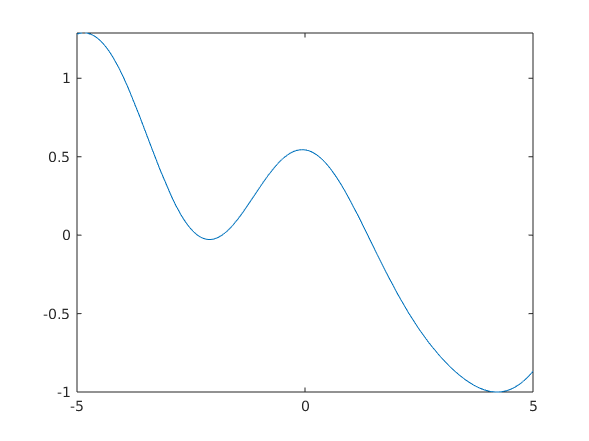

fplot(position)

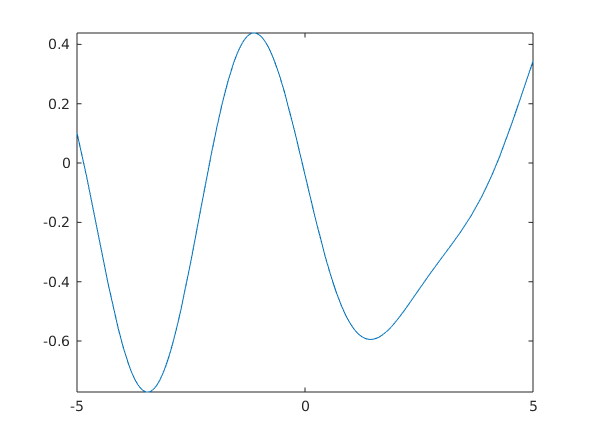

fplot(velocity)

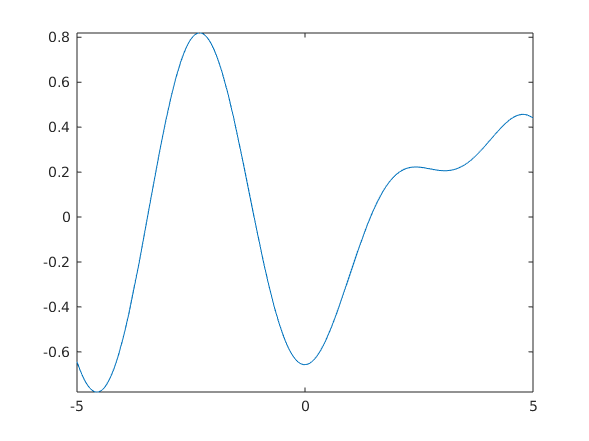

fplot(acceleration)

sim.simxStartSimulation(clientID, sim.simx_opmode_oneshot);
[returnCode,joint_position1]=sim.simxGetJointPosition(clientID,joint1,sim.simx_opmode_streaming)

returnCode = 1

joint_position1 = single
43

[returnCode,joint_position2]=sim.simxGetJointPosition(clientID,joint2,sim.simx_opmode_streaming)

returnCode = 1

joint_position2 = single
43

[returnCode,joint_position3]=sim.simxGetJointPosition(clientID,joint3,sim.simx_opmode_streaming)

returnCode = 1

joint_position3 = single
43

controller_gain =0.005

controller_gain = 0.0050

controller_gain = 0.01

controller_gain = 0.0100

Kp = 3*controller_gain;
Kd = 1.5*controller_gain;
Ki = 2*controller_gain;   

measured_pos = zeros(3, 500000);
reference_pos = zeros(3, 500000);
measured_vel = zeros(3, 500000);
reference_vel = zeros(1, 500000);
time_axis = zeros(3, 500000);
error = zeros(3, 500000);
derror = zeros(3, 500000);
ierror = zeros(3, 500000);
torque = zeros(3, 500000);
computed = zeros(3, 500000);
correction = zeros(3, 500000);
i = 1;

queue = [0 0; 0 0; 0 0];

t0 = datetime('now');
t1 = t0;
start = t0;
integral = 0

integral = 0

u = [0 0 0];
while seconds(t1-start)<=60
    t1 = datetime('now');
    frame_period = (seconds(t1-start)/i);
    frame_rate = 1/frame_period;
    
    for j = 1:3
        [returnCode,joint_position]=sim.simxGetJointPosition(clientID,joints(j),sim.simx_opmode_buffer);
        
        
        queue(j,2) = queue(j,1);
        queue(j,1) = joint_position;
        
        v = (queue(j,1)-queue(j,2))/seconds(t1-t0);
        measured_vel(j, i) = v;
        
        %integral = integral + (position(seconds(t1-start)) - joint_position)*seconds(t1-t0);
        integral = 0;
        
        
        
        %feedforward = 490.5*sin(position(seconds(t1-start))) + (134.7+25)*acceleration(seconds(t1-start));
        feedforward = 0;
        c = Kp*(position(seconds(t1-start)) - joint_position) + Kd*(velocity(seconds(t1-start)) - v) + Ki*integral;
        u(j) = c + feedforward;
        torque(j, i) = double(u(j));
        computed(j, i) = feedforward;
        correction(j, i) = c;
        
        time_axis(j, i) = seconds(t1-start);
        
        measured_pos(j, i) = joint_position;
        reference_pos(j, i) = position(seconds(t1-start));
        
        reference_vel(j, i) = velocity(seconds(t1-start));
        
        error(j, i) = (position(seconds(t1-start)) - joint_position);
        derror(j, i) = velocity(seconds(t1-start)) - v;
        ierror(j, i) = integral;
    end
    sim.simxPauseCommunication(clientID,1);
    for j=1:3
        sim.simxSetJointTargetVelocity(clientID, joints(j), sign(u(j))*10e10, sim.simx_opmode_oneshot);
        sim.simxSetJointForce(clientID, joints(j), abs(u(j)), sim.simx_opmode_oneshot);
        
    end
    sim.simxPauseCommunication(clientID,0);
    
    i = i+1;
    t0=t1;
    
    pause(0.05)
end

joint_position = single
3.9522

joint_position = single
3.4873

joint_position = single
24.4087

u =    -1.0378   -0.9139   -6.4866


joint_position = single
16.0231

joint_position = single
3.6228

joint_position = single
-19.3572

u =    -0.7459   -0.1081    1.5591


joint_position = single
17.1029

joint_position = single
6.7753

joint_position = single
-30.3271

u =    -0.5642   -0.3465    1.3943


joint_position = single
13.6261

joint_position = single
9.5077

joint_position = single
-16.0057

u =    -0.1987   -0.4642   -0.4248


joint_position = single
12.8435

joint_position = single
8.1773

joint_position = single
-6.6665

u =    -0.3000   -0.0933   -0.9474


joint_position = single
11.0609

joint_position = single
5.6535

joint_position = single
-2.6603

u =    -0.2201   -0.0058   -0.2155


joint_position = single
10.6709

joint_position = single
6.2588

joint_position = single
-5.7341

u =    -0.2621   -0.3158    0.7317


joint_position = single
9.8530

joint_position = single
6.8912

joint_position = single
-8.1459

u =    -0.1319   -0.3615    0.7581


joint_position = single
6.9410

joint_position = single
7.7052

joint_position = single
-11.5427

u =     0.3388   -0.4059    0.9872


joint_position = single
6.4305

joint_position = single
6.6775

joint_position = single
-10.1942

u =    -0.0969    0.0112   -0.0133


joint_position = single
5.9234

joint_position = single
5.7265

joint_position = single
-9.1951

u =    -0.0970   -0.0039    0.0605


joint_position = single
4.9602

joint_position = single
5.4798

joint_position = single
-10.8271

u =    -0.0078   -0.1433    0.5776


joint_position = single
4.1529

joint_position = single
6.3597

joint_position = single
-12.8238

u =    -0.0057   -0.3646    0.7100


joint_position = single
3.6061

joint_position = single
7.0126

joint_position = single
-11.6470

u =    -0.0138   -0.3713    0.0770


joint_position = single
2.2647

joint_position = single
7.4161

joint_position = single
-9.2626

u =     0.1478   -0.3171   -0.1693


joint_position = single
-0.4027

joint_position = single
9.1250

joint_position = single
-11.8910

u =     0.4908   -0.6193    0.8281


joint_position = single
-0.8430

joint_position = single
9.8750

joint_position = single
-13.0834

u =     0.0877   -0.4685    0.6031


joint_position = single
-1.3592

joint_position = single
10.0891

joint_position = single
-12.4987

u =     0.1239   -0.3726    0.2273


joint_position = single
-1.7693

joint_position = single
9.4770

joint_position = single
-10.1783

u =     0.1067   -0.1917   -0.1693


joint_position = single
-2.2078

joint_position = single
8.0231

joint_position = single
-7.6674

u =     0.1239    0.0116   -0.2777


joint_position = single
-2.4585

joint_position = single
6.2775

joint_position = single
-3.7939

u =     0.0892    0.0810   -0.5711


joint_position = single
-2.9578

joint_position = single
5.7744

joint_position = single
-2.1198

u =     0.1537   -0.1075   -0.2747


joint_position = single
-3.8233

joint_position = single
5.9711

joint_position = single
-1.4980

u =     0.2574   -0.2462   -0.1060


joint_position = single
-4.6917

joint_position = single
6.9950

joint_position = single
-2.3068

u =     0.2224   -0.3692    0.1433


joint_position = single
-6.5935

joint_position = single
8.0309

joint_position = single
-4.8584

u =     0.6785   -0.5480    0.8007


joint_position = single
-7.6962

joint_position = single
8.8777

joint_position = single
-6.2189

u =     0.4146   -0.4598    0.4202


joint_position = single
-8.0243

joint_position = single
8.6979

joint_position = single
-3.3569

u =     0.2768   -0.2547   -0.5058


joint_position = single
-8.1414

joint_position = single
8.3551

joint_position = single
-0.0613

u =     0.2343   -0.2213   -0.6025


joint_position = single
-7.6721

joint_position = single
7.3653

joint_position = single
2.8629

u =     0.1176   -0.0788   -0.6271


joint_position = single
-7.6765

joint_position = single
6.8319

joint_position = single
3.2677

u =     0.2002   -0.1380   -0.2032


joint_position = single
-7.9129

joint_position = single
7.4654

joint_position = single
0.2036

u =     0.2466   -0.3629    0.4846


joint_position = single
-8.6217

joint_position = single
7.9931

joint_position = single
-1.2731

u =     0.3629   -0.3717    0.2890


joint_position = single
-9.0790

joint_position = single
8.3658

joint_position = single
-1.8604

u =     0.3328   -0.3568    0.1423


joint_position = single
-9.0196

joint_position = single
8.3078

joint_position = single
-2.2377

u =     0.2272   -0.2684    0.1139


joint_position = single
-8.6558

joint_position = single
7.9535

joint_position = single
-2.8107

u =     0.1507   -0.1936    0.1762


joint_position = single
-7.8693

joint_position = single
7.9103

joint_position = single
-5.3854

u =     0.0667   -0.2605    0.5845


joint_position = single
-7.1723

joint_position = single
7.5915

joint_position = single
-5.9674

u =     0.0662   -0.2040    0.2475


joint_position = single
-6.7055

joint_position = single
6.7989

joint_position = single
-3.8079

u =     0.0884   -0.0937   -0.2983


joint_position = single
-6.5785

joint_position = single
6.7238

joint_position = single
-2.7904

u =     0.1432   -0.2168   -0.1427


joint_position = single
-6.4331

joint_position = single
7.3344

joint_position = single
-3.2158

u =     0.1395   -0.3524    0.1396


joint_position = single
-6.6543

joint_position = single
8.2121

joint_position = single
-5.5100

u =     0.2075   -0.4174    0.5108


joint_position = single
-6.4354

joint_position = single
8.6172

joint_position = single
-6.3632

u =     0.1279   -0.3558    0.3112


joint_position = single
-5.8735

joint_position = single
8.3408

joint_position = single
-3.2727

u =     0.0647   -0.2343   -0.3977


joint_position = single
-4.1818

joint_position = single
7.6647

joint_position = single
-1.7790

u =    -0.2642   -0.1095   -0.2936


joint_position = single
-3.0961

joint_position = single
7.3060

joint_position = single
-0.8920

u =    -0.1306   -0.1774   -0.1603


joint_position = single
-2.5711

joint_position = single
7.0957

joint_position = single
0.7662

u =    -0.0566   -0.1916   -0.3956


joint_position = single
-2.4097

joint_position = single
7.0441

joint_position = single
2.0935

u =     0.0196   -0.2233   -0.3383


joint_position = single
-2.3741

joint_position = single
7.5561

joint_position = single
1.6756

u =     0.0442   -0.3422    0.0068


joint_position = single
-2.5930

joint_position = single
8.6182

joint_position = single
0.3674

u =     0.1001   -0.4784    0.2172


joint_position = single
-2.4446

joint_position = single
8.6890

joint_position = single
1.4109

u =     0.0278   -0.2916   -0.2561


joint_position = single
-2.1331

joint_position = single
8.3527

joint_position = single
3.2642

u =    -0.0025   -0.2118   -0.4150


joint_position = single
-1.4219

joint_position = single
8.0061

joint_position = single
4.0209

u =    -0.1452   -0.1705   -0.3196


joint_position = single
0.1601

joint_position = single
7.5402

joint_position = single
2.4615

u =    -0.1960   -0.1855    0.0906


joint_position = single
0.5151

joint_position = single
7.9682

joint_position = single
-1.0650

u =    -0.1237   -0.3674    0.9876


joint_position = single
1.4166

joint_position = single
7.1919

joint_position = single
-2.0164

u =    -0.2301   -0.0719    0.2390


joint_position = single
2.1196

joint_position = single
6.9709

joint_position = single
-2.4860

u =    -0.1980   -0.1772    0.1512


joint_position = single
2.3010

joint_position = single
7.0901

joint_position = single
-3.2368

u =    -0.1244   -0.2514    0.2915


joint_position = single
2.2300

joint_position = single
7.6540

joint_position = single
-4.9450

u =    -0.0581   -0.3477    0.4845


joint_position = single
1.9414

joint_position = single
8.1816

joint_position = single
-5.9106

u =     0.0143   -0.3904    0.4304


joint_position = single
2.0917

joint_position = single
8.1133

joint_position = single
-4.7225

u =    -0.0965   -0.2325   -0.1039


joint_position = single
2.5515

joint_position = single
7.8044

joint_position = single
-2.6448

u =    -0.2006   -0.1543   -0.4739


joint_position = single
2.8450

joint_position = single
7.9588

joint_position = single
-0.8100

u =    -0.1481   -0.2722   -0.3628


joint_position = single
3.0786

joint_position = single
8.0075

joint_position = single
-0.3180

u =    -0.1550   -0.2534   -0.1222


joint_position = single
3.5673

joint_position = single
7.5322

joint_position = single
2.0828

u =    -0.1980   -0.1355   -0.5132


joint_position = single
2.9187

joint_position = single
7.9891

joint_position = single
1.7123

u =    -0.0046   -0.2938   -0.0029


joint_position = single
2.4789

joint_position = single
8.5434

joint_position = single
-0.0930

u =     0.0410   -0.3947    0.4666


joint_position = single
2.3909

joint_position = single
8.5822

joint_position = single
-0.6965

u =    -0.0501   -0.2616    0.1474


joint_position = single
2.4953

joint_position = single
8.3042

joint_position = single
-0.2400

u =    -0.0982   -0.1715   -0.1090


joint_position = single
3.0774

joint_position = single
7.5337

joint_position = single
1.9422

u =    -0.2097   -0.0598   -0.5113


joint_position = single
3.1725

joint_position = single
7.0734

joint_position = single
3.3622

u =    -0.1152   -0.0867   -0.4680


joint_position = single
3.0667

joint_position = single
7.0020

joint_position = single
3.5046

u =    -0.0642   -0.1896   -0.1305


joint_position = single
2.8180

joint_position = single
7.2846

joint_position = single
2.3913

u =    -0.0110   -0.2908    0.2392


joint_position = single
1.6092

joint_position = single
8.2187

joint_position = single
-0.7425

u =     0.2177   -0.4427    0.7033


joint_position = single
1.3185

joint_position = single
8.3300

joint_position = single
-1.1544

u =     0.0445   -0.2748    0.1516


joint_position = single
0.9955

joint_position = single
8.3042

joint_position = single
-1.0406

u =     0.0430   -0.2386    0.0124


joint_position = single
1.1415

joint_position = single
7.9710

joint_position = single
-0.0201

u =    -0.0694   -0.1428   -0.2745


joint_position = single
1.4038

joint_position = single
7.2918

joint_position = single
2.3034

u =    -0.0876   -0.0847   -0.5077


joint_position = single
1.2773

joint_position = single
7.1086

joint_position = single
3.2837

u =    -0.0074   -0.1703   -0.3028


joint_position = single
0.9816

joint_position = single
7.2877

joint_position = single
2.9491

u =     0.0348   -0.2519   -0.0163


joint_position = single
0.1251

joint_position = single
7.9592

joint_position = single
0.9096

u =     0.2208   -0.4095    0.5033


joint_position = single
-0.4817

joint_position = single
8.2902

joint_position = single
-0.2362

u =     0.1456   -0.3167    0.2527


joint_position = single
-0.5944

joint_position = single
8.2950

joint_position = single
-0.2680

u =     0.0499   -0.2484    0.0183


joint_position = single
-0.3345

joint_position = single
7.7150

joint_position = single
1.6097

u =    -0.0429   -0.1105   -0.4362


joint_position = single
-0.1907

joint_position = single
7.4097

joint_position = single
2.6100

u =    -0.0305   -0.1447   -0.3317


joint_position = single
-0.2317

joint_position = single
7.2549

joint_position = single
3.1048

u =     0.0146   -0.1868   -0.1947


joint_position = single
-0.4368

joint_position = single
7.3611

joint_position = single
2.6723

u =     0.0629   -0.2489    0.0266


joint_position = single
-1.1243

joint_position = single
7.9857

joint_position = single
0.5382

u =     0.1643   -0.3630    0.3946


joint_position = single
-1.5501

joint_position = single
8.2062

joint_position = single
-0.5612

u =     0.1506   -0.3051    0.2908


joint_position = single
-1.6235

joint_position = single
8.1216

joint_position = single
-0.4505

u =     0.0598   -0.2302   -0.0138


joint_position = single
-1.3970

joint_position = single
7.8495

joint_position = single
0.1009

u =    -0.0223   -0.1692   -0.1522


joint_position = single
-1.1292

joint_position = single
7.2891

joint_position = single
2.2365

u =    -0.0228   -0.1183   -0.4778


joint_position = single
-1.1938

joint_position = single
7.1879

joint_position = single
3.2252

u =     0.0450   -0.1976   -0.3448


joint_position = single
-1.4781

joint_position = single
7.4691

joint_position = single
2.8499

u =     0.0927   -0.2868   -0.0193


joint_position = single
-2.2625

joint_position = single
8.2107

joint_position = single
0.7509

u =     0.1886   -0.3767    0.3145


joint_position = single
-2.4132

joint_position = single
8.4626

joint_position = single
-0.1161

u =     0.0899   -0.3074    0.1474


joint_position = single
-2.3181

joint_position = single
8.1111

joint_position = single
0.8860

u =     0.0366   -0.1662   -0.2830


joint_position = single
-1.0715

joint_position = single
7.1935

joint_position = single
3.3612

u =    -0.1808   -0.0765   -0.5137


joint_position = single
-0.9093

joint_position = single
7.0739

joint_position = single
3.2047

u =    -0.0261   -0.1907   -0.0648


joint_position = single
-0.9606

joint_position = single
7.4561

joint_position = single
1.5244

u =     0.0288   -0.3117    0.2849


joint_position = single
-1.1544

joint_position = single
7.8024

joint_position = single
0.3654

u =     0.0757   -0.3369    0.2873


joint_position = single
-0.8174

joint_position = single
7.6531

joint_position = single
2.5687

u =    -0.0063   -0.2302   -0.2239


joint_position = single
-0.5326

joint_position = single
7.4367

joint_position = single
3.5628

u =    -0.0625   -0.1802   -0.3571


joint_position = single
-0.1511

joint_position = single
7.4525

joint_position = single
5.4946

u =    -0.0788   -0.2355   -0.5507


joint_position = single
-0.0898

joint_position = single
7.4906

joint_position = single
6.0016

u =    -0.0207   -0.2424   -0.3134


joint_position = single
-0.0179

joint_position = single
7.4985

joint_position = single
7.1663

u =    -0.0206   -0.2338   -0.4458


joint_position = single
-0.0746

joint_position = single
7.5177

joint_position = single
8.3625

u =     0.0086   -0.2364   -0.5280


joint_position = single
-0.8929

joint_position = single
8.4617

joint_position = single
6.8985

u =     0.1642   -0.4236    0.0430


joint_position = single
-0.9437

joint_position = single
8.6609

joint_position = single
6.5336

u =     0.0364   -0.3123   -0.1119


joint_position = single
-0.8636

joint_position = single
8.6961

joint_position = single
6.6238

u =     0.0077   -0.2705   -0.2189


joint_position = single
-0.7646

joint_position = single
8.1859

joint_position = single
7.8921

u =    -0.0006   -0.1339   -0.5198


joint_position = single
-0.1302

joint_position = single
7.8024

joint_position = single
9.0446

u =    -0.0945   -0.1740   -0.4503


joint_position = single
0.5965

joint_position = single
7.3689

joint_position = single
8.8163

u =    -0.1559   -0.1356   -0.2185


joint_position = single
0.6919

joint_position = single
7.6545

joint_position = single
5.8993

u =    -0.0358   -0.2820    0.3988


joint_position = single
0.7781

joint_position = single
7.4487

joint_position = single
4.4797

u =    -0.0342   -0.1791    0.1396


joint_position = single
0.7974

joint_position = single
7.4553

joint_position = single
3.1724

u =    -0.0210   -0.2181    0.1923


joint_position = single
0.3162

joint_position = single
8.0944

joint_position = single
0.7647

u =     0.1280   -0.4062    0.6319


joint_position = single
0.2900

joint_position = single
8.2548

joint_position = single
-0.2134

u =     0.0066   -0.2702    0.2144


joint_position = single
0.6568

joint_position = single
8.0197

joint_position = single
0.2896

u =    -0.1069   -0.1663   -0.1324


joint_position = single
1.2632

joint_position = single
7.3864

joint_position = single
2.3026

u =    -0.1459   -0.0825   -0.4574


joint_position = single
1.3863

joint_position = single
7.1822

joint_position = single
3.1062

u =    -0.0586   -0.1495   -0.2829


joint_position = single
1.3071

joint_position = single
7.3542

joint_position = single
2.5933

u =    -0.0069   -0.2410    0.0454


joint_position = single
0.7042

joint_position = single
8.0506

joint_position = single
0.4285

u =     0.1247   -0.3731    0.4664


joint_position = single
0.3476

joint_position = single
8.3817

joint_position = single
-0.4598

u =     0.0620   -0.2820    0.1659


joint_position = single
0.5116

joint_position = single
8.2149

joint_position = single
0.0498

u =    -0.0388   -0.1822   -0.1165


joint_position = single
1.2501

joint_position = single
7.4548

joint_position = single
2.4695

u =    -0.1528   -0.0615   -0.5006


joint_position = single
1.4480

joint_position = single
7.1219

joint_position = single
3.7475

u =    -0.0564   -0.1311   -0.3197


joint_position = single
1.3577

joint_position = single
7.2539

joint_position = single
3.2421

u =     0.0024   -0.2224    0.0352


joint_position = single
0.7676

joint_position = single
7.9235

joint_position = single
1.0766

u =     0.1554   -0.3882    0.5576


joint_position = single
0.3372

joint_position = single
8.3351

joint_position = single
-0.3061

u =     0.1055   -0.3114    0.3248


joint_position = single
0.3080

joint_position = single
8.3193

joint_position = single
-0.2237

u =     0.0240   -0.2198    0.0113


joint_position = single
0.8019

joint_position = single
7.8685

joint_position = single
1.2522

u =    -0.0972   -0.1189   -0.3085


joint_position = single
1.1781

joint_position = single
7.2840

joint_position = single
3.0936

u =    -0.1011   -0.0480   -0.5188


joint_position = single
1.3543

joint_position = single
7.1916

joint_position = single
3.3252

u =    -0.0452   -0.1719   -0.1143


joint_position = single
1.3158

joint_position = single
7.2626

joint_position = single
2.9733

u =    -0.0023   -0.2084    0.0273


joint_position = single
0.8780

joint_position = single
7.8413

joint_position = single
1.0007

u =     0.0893   -0.3239    0.3939


joint_position = single
0.4416

joint_position = single
8.2193

joint_position = single
-0.1917

u =     0.1258   -0.3153    0.3376


joint_position = single
0.3985

joint_position = single
8.2329

joint_position = single
-0.0353

u =     0.0242   -0.2219   -0.0020


joint_position = single
0.8864

joint_position = single
7.7338

joint_position = single
1.7128

u =    -0.1251   -0.0752   -0.4758


joint_position = single
1.1362

joint_position = single
7.4378

joint_position = single
2.7159

u =    -0.0540   -0.1393   -0.2447


joint_position = single
1.2300

joint_position = single
7.2885

joint_position = single
3.3530

u =    -0.0343   -0.1518   -0.2416


joint_position = single
1.1332

joint_position = single
7.4079

joint_position = single
2.9387

u =     0.0126   -0.2191    0.0222


joint_position = single
0.5477

joint_position = single
8.0137

joint_position = single
0.9763

u =     0.1656   -0.3740    0.5174


joint_position = single
0.3025

joint_position = single
8.2851

joint_position = single
-0.0327

u =     0.0723   -0.2826    0.2531


joint_position = single
0.4853

joint_position = single
8.1226

joint_position = single
0.4432

u =    -0.0376   -0.1735   -0.1155


joint_position = single
0.8387

joint_position = single
7.4562

joint_position = single
2.5039

u =    -0.0743   -0.0561   -0.4870


joint_position = single
1.2843

joint_position = single
7.2327

joint_position = single
3.2213

u =    -0.1342   -0.1305   -0.2664


joint_position = single
1.2922

joint_position = single
7.3518

joint_position = single
2.6506

u =    -0.0151   -0.2196    0.0624


joint_position = single
0.7573

joint_position = single
7.9885

joint_position = single
0.5419

u =     0.1460   -0.3858    0.5755


joint_position = single
0.4489

joint_position = single
8.2477

joint_position = single
-0.2888

u =     0.0776   -0.2787    0.2123


joint_position = single
0.5177

joint_position = single
8.1621

joint_position = single
0.2252

u =    -0.0096   -0.1975   -0.1205


joint_position = single
1.1217

joint_position = single
7.5328

joint_position = single
2.3408

u =    -0.1271   -0.0795   -0.4578


joint_position = single
1.2816

joint_position = single
7.2963

joint_position = single
3.2754

u =    -0.0540   -0.1368   -0.3046


joint_position = single
1.1973

joint_position = single
7.3906

joint_position = single
2.9399

u =     0.0050   -0.2174    0.0042


joint_position = single
1.0228

joint_position = single
7.5947

joint_position = single
0.9695

u =     0.0375   -0.2566    0.4990


joint_position = single
0.3941

joint_position = single
8.2036

joint_position = single
0.2229

u =     0.1296   -0.3370    0.1569


joint_position = single
0.3033

joint_position = single
8.2707

joint_position = single
-0.0940

u =     0.0385   -0.2426    0.1107


joint_position = single
0.5734

joint_position = single
7.9704

joint_position = single
0.8848

u =    -0.0503   -0.1527   -0.2080


joint_position = single
1.0927

joint_position = single
7.3578

joint_position = single
2.8304

u =    -0.1442   -0.0378   -0.5673


joint_position = single
1.1364

joint_position = single
7.2458

joint_position = single
3.2044

u =    -0.0191   -0.1708   -0.1482


joint_position = single
0.9091

joint_position = single
7.5427

joint_position = single
2.0540

u =     0.0565   -0.2803    0.2650


joint_position = single
0.2318

joint_position = single
8.1655

joint_position = single
-0.1246

u =     0.1636   -0.3550    0.4984


joint_position = single
0.0574

joint_position = single
8.2408

joint_position = single
-0.6852

u =     0.0709   -0.2432    0.1991


joint_position = single
0.2108

joint_position = single
8.0704

joint_position = single
-0.1616

u =    -0.0124   -0.1820   -0.0769


joint_position = single
0.6837

joint_position = single
7.4785

joint_position = single
1.9044

u =    -0.1137   -0.0498   -0.5510


joint_position = single
0.7789

joint_position = single
7.1647

joint_position = single
3.4375

u =    -0.0179   -0.1198   -0.4127


joint_position = single
0.6452

joint_position = single
7.2925

joint_position = single
3.5284

u =     0.0438   -0.2265   -0.1036


joint_position = single
0.1465

joint_position = single
7.7587

joint_position = single
2.1657

u =     0.1264   -0.3014    0.2444


joint_position = single
-0.4529

joint_position = single
8.4355

joint_position = single
-0.0212

u =     0.2052   -0.4091    0.6246


joint_position = single
-0.4774

joint_position = single
8.3969

joint_position = single
-0.2614

u =     0.0488   -0.2144    0.0891


joint_position = single
-0.1855

joint_position = single
8.1835

joint_position = single
0.3859

u =    -0.0394   -0.1608   -0.1477


joint_position = single
0.8428

joint_position = single
7.1143

joint_position = single
3.5909

u =    -0.2141    0.0457   -0.7614


joint_position = single
0.9204

joint_position = single
7.0009

joint_position = single
4.0960

u =    -0.0162   -0.1490   -0.2223


joint_position = single
0.9477

joint_position = single
7.0504

joint_position = single
3.4526

u =    -0.0016   -0.1894    0.0648


joint_position = single
0.6469

joint_position = single
7.6710

joint_position = single
1.3872

u =     0.0962   -0.3666    0.5565


joint_position = single
0.2526

joint_position = single
8.3058

joint_position = single
-0.3508

u =     0.1123   -0.3529    0.4223


joint_position = single
-0.0607

joint_position = single
8.4388

joint_position = single
-0.5102

u =     0.1168   -0.2522    0.0910


joint_position = single
-0.0583

joint_position = single
8.4639

joint_position = single
0.0133

u =     0.0371   -0.2232   -0.0735


joint_position = single
0.3899

joint_position = single
7.9068

joint_position = single
2.0042

u =    -0.0973   -0.0488   -0.5664


joint_position = single
1.0315

joint_position = single
7.4115

joint_position = single
3.5989

u =    -0.1314   -0.0786   -0.4130


joint_position = single
1.2925

joint_position = single
7.2290

joint_position = single
3.8640

u =    -0.0719   -0.1292   -0.1501


joint_position = single
1.2234

joint_position = single
7.5630

joint_position = single
1.9601

u =     0.0155   -0.2531    0.3501


joint_position = single
0.6940

joint_position = single
8.1988

joint_position = single
-0.3130

u =     0.1546   -0.3703    0.6332


joint_position = single
0.6378

joint_position = single
8.2818

joint_position = single
-0.9398

u =     0.0328   -0.2267    0.2040


joint_position = single
0.9012

joint_position = single
8.1373

joint_position = single
-0.4818

u =    -0.0595   -0.1643   -0.0715


joint_position = single
1.4593

joint_position = single
7.6703

joint_position = single
1.1684

u =    -0.1233   -0.0893   -0.3494


joint_position = single
1.7286

joint_position = single
7.1977

joint_position = single
3.0317

u =    -0.0824   -0.0504   -0.5428


joint_position = single
1.6913

joint_position = single
7.2541

joint_position = single
3.2945

u =    -0.0023   -0.1885   -0.1124


joint_position = single
1.3361

joint_position = single
7.6897

joint_position = single
2.0826

u =     0.0956   -0.3063    0.3021


joint_position = single
0.7354

joint_position = single
8.3402

joint_position = single
0.1383

u =     0.1455   -0.3470    0.4474


joint_position = single
0.7151

joint_position = single
8.4187

joint_position = single
-0.0625

u =     0.0246   -0.2336    0.0974


joint_position = single
1.0647

joint_position = single
8.0457

joint_position = single
1.1982

u =    -0.0634   -0.1249   -0.2540


joint_position = single
1.7927

joint_position = single
7.4060

joint_position = single
3.1748

u =    -0.2119   -0.0086   -0.5927


joint_position = single
1.9827

joint_position = single
7.2469

joint_position = single
3.5367

u =    -0.0614   -0.1439   -0.1452


joint_position = single
1.9298

joint_position = single
7.3994

joint_position = single
2.6428

u =    -0.0051   -0.2245    0.1998


joint_position = single
1.3738

joint_position = single
8.0597

joint_position = single
0.3844

u =     0.1047   -0.3328    0.4661


joint_position = single
1.1722

joint_position = single
8.2513

joint_position = single
-0.3656

u =     0.0543   -0.2608    0.2438


joint_position = single
1.2539

joint_position = single
8.1692

joint_position = single
-0.0230

u =    -0.0183   -0.1931   -0.0320


joint_position = single
1.4441

joint_position = single
7.6084

joint_position = single
1.8687

u =    -0.0591   -0.0449   -0.5229


joint_position = single
1.9962

joint_position = single
7.2685

joint_position = single
3.1729

u =    -0.1327   -0.1196   -0.3124


joint_position = single
1.9323

joint_position = single
7.3423

joint_position = single
2.9778

u =    -0.0093   -0.2075   -0.0065


joint_position = single
1.3724

joint_position = single
7.9382

joint_position = single
1.0496

u =     0.1002   -0.3259    0.3812


joint_position = single
0.9925

joint_position = single
8.2835

joint_position = single
-0.1404

u =     0.1030   -0.3136    0.3580


joint_position = single
1.0143

joint_position = single
8.2315

joint_position = single
0.0167

u =    -0.0077   -0.2082   -0.0071


joint_position = single
1.6102

joint_position = single
7.6203

joint_position = single
1.9809

u =    -0.1861   -0.0344   -0.5736


joint_position = single
1.8904

joint_position = single
7.2027

joint_position = single
3.5027

u =    -0.0936   -0.1005   -0.4132


joint_position = single
1.8677

joint_position = single
7.1903

joint_position = single
3.5727

u =    -0.0270   -0.1895   -0.1031


joint_position = single
1.0967

joint_position = single
7.9975

joint_position = single
0.7990

u =     0.1343   -0.3724    0.5235


joint_position = single
0.6710

joint_position = single
8.3381

joint_position = single
-0.6664

u =     0.1108   -0.3202    0.4237


joint_position = single
0.6483

joint_position = single
8.2721

joint_position = single
-0.9352

u =     0.0028   -0.2166    0.1032


joint_position = single
0.9402

joint_position = single
7.9920

joint_position = single
-0.2279

u =    -0.0912   -0.1482   -0.1683


joint_position = single
1.3348

joint_position = single
7.4154

joint_position = single
1.7930

u =    -0.1120   -0.0827   -0.4803


joint_position = single
1.3414

joint_position = single
7.1561

joint_position = single
3.1138

u =    -0.0294   -0.1314   -0.4407


joint_position = single
1.1241

joint_position = single
7.3477

joint_position = single
2.9451

u =     0.0214   -0.2488   -0.0432


joint_position = single
0.3042

joint_position = single
8.0657

joint_position = single
0.9102

u =     0.2150   -0.4208    0.5152


joint_position = single
-0.0843

joint_position = single
8.4219

joint_position = single
-0.1458

u =     0.0922   -0.3202    0.2349


joint_position = single
-0.0796

joint_position = single
8.3469

joint_position = single
0.2098

u =     0.0074   -0.2240   -0.0950


joint_position = single
0.8201

joint_position = single
7.3725

joint_position = single
3.3248

u =    -0.2058   -0.0151   -0.7386


joint_position = single
1.0006

joint_position = single
7.1613

joint_position = single
4.0684

u =    -0.0728   -0.1571   -0.3095


joint_position = single
0.9856

joint_position = single
7.1658

joint_position = single
3.6302

u =    -0.0240   -0.2137   -0.0099


joint_position = single
0.7058

joint_position = single
7.5879

joint_position = single
1.9689

u =     0.0573   -0.3428    0.4007


joint_position = single
0.0409

joint_position = single
8.2343

joint_position = single
-0.1770

u =     0.1446   -0.3885    0.4757


joint_position = single
-0.0736

joint_position = single
8.3185

joint_position = single
-0.5671

u =     0.0323   -0.2728    0.1210


joint_position = single
0.1318

joint_position = single
8.1122

joint_position = single
0.1716

u =    -0.0470   -0.2033   -0.1558


joint_position = single
0.4429

joint_position = single
7.8059

joint_position = single
1.1542

u =    -0.0966   -0.1565   -0.2930


joint_position = single
0.8270

joint_position = single
7.1913

joint_position = single
3.2581

u =    -0.1053   -0.0944   -0.5257


joint_position = single
0.8026

joint_position = single
7.2003

joint_position = single
3.2606

u =    -0.0206   -0.2217   -0.1017


joint_position = single
0.5830

joint_position = single
7.4833

joint_position = single
2.2952

u =     0.0273   -0.2903    0.1400


joint_position = single
-0.1263

joint_position = single
8.1486

joint_position = single
0.1920

u =     0.1900   -0.4264    0.5539


joint_position = single
-0.3810

joint_position = single
8.3232

joint_position = single
-0.5078

u =     0.0586   -0.2885    0.1516


joint_position = single
-0.3225

joint_position = single
8.2046

joint_position = single
0.6058

u =    -0.0096   -0.2185   -0.3172


joint_position = single
0.4102

joint_position = single
7.2768

joint_position = single
2.9132

u =    -0.1642   -0.0342   -0.5580


joint_position = single
0.4562

joint_position = single
7.1230

joint_position = single
3.5065

u =    -0.0292   -0.1766   -0.2649


joint_position = single
0.3371

joint_position = single
7.2787

joint_position = single
2.8802

u =     0.0115   -0.2533    0.0395


joint_position = single
-0.3043

joint_position = single
7.9963

joint_position = single
0.5294

u =     0.1759   -0.4318    0.6021


joint_position = single
-0.8096

joint_position = single
8.3224

joint_position = single
-1.1323

u =     0.1246   -0.3175    0.3682


joint_position = single
-0.7935

joint_position = single
8.1451

joint_position = single
-1.0479

u =     0.0186   -0.2013    0.0091


joint_position = single
-0.2283

joint_position = single
7.7912

joint_position = single
-0.0490

u =    -0.1142   -0.1586   -0.2122


joint_position = single
-0.0489

joint_position = single
7.5428

joint_position = single
0.8886

u =    -0.0464   -0.1592   -0.2781


joint_position = single
0.0579

joint_position = single
7.1032

joint_position = single
3.2320

u =    -0.0237   -0.1163   -0.6050


joint_position = single
-0.0831

joint_position = single
7.2365

joint_position = single
3.3186

u =     0.0413   -0.2496   -0.1200


joint_position = single
-0.5796

joint_position = single
7.7222

joint_position = single
1.1051

u =     0.1189   -0.3245    0.4082


joint_position = single
-1.1910

joint_position = single
8.4393

joint_position = single
0.3198

u =     0.2008   -0.4376    0.2012


joint_position = single
-1.2042

joint_position = single
8.5193

joint_position = single
0.1366

u =     0.0443   -0.2668    0.0394


joint_position = single
-0.7144

joint_position = single
7.9233

joint_position = single
1.8859

u =    -0.1072   -0.0673   -0.5320


joint_position = single
0.0147

joint_position = single
7.3325

joint_position = single
3.3729

u =    -0.1565   -0.0800   -0.4273


joint_position = single
0.1627

joint_position = single
7.1936

joint_position = single
3.4567

u =    -0.0368   -0.1697   -0.1182


joint_position = single
0.2794

joint_position = single
7.1754

joint_position = single
1.7889

u =    -0.0223   -0.2020    0.2919


joint_position = single
0.0985

joint_position = single
7.7139

joint_position = single
0.5888

u =     0.0559   -0.3648    0.3134


joint_position = single
-0.3293

joint_position = single
8.2085

joint_position = single
-0.5305

u =     0.1108   -0.3379    0.2611


joint_position = single
-0.3471

joint_position = single
8.2657

joint_position = single
-0.3376

u =     0.0275   -0.2505   -0.0278


joint_position = single
-0.0690

joint_position = single
8.0306

joint_position = single
0.9699

u =    -0.0444   -0.1767   -0.2976


joint_position = single
0.5693

joint_position = single
7.4597

joint_position = single
3.0229

u =    -0.1778   -0.0531   -0.6392


joint_position = single
0.6943

joint_position = single
7.4032

joint_position = single
3.3992

u =    -0.0302   -0.1959   -0.1606


joint_position = single
0.5074

joint_position = single
7.6669

joint_position = single
2.3668

u =     0.0503   -0.2844    0.2195


joint_position = single
0.0237

joint_position = single
8.2614

joint_position = single
0.2628

u =     0.1138   -0.3518    0.4349


joint_position = single
0.0997

joint_position = single
8.2667

joint_position = single
-0.1836

u =    -0.0067   -0.2324    0.1444


joint_position = single
0.5586

joint_position = single
7.9137

joint_position = single
0.7088

u =    -0.0916   -0.1488   -0.1833


joint_position = single
0.9290

joint_position = single
7.5248

joint_position = single
1.9040

u =    -0.1075   -0.1055   -0.3538


joint_position = single
1.1465

joint_position = single
7.1676

joint_position = single
3.1663

u =    -0.0663   -0.1145   -0.3677


joint_position = single
1.1395

joint_position = single
7.2100

joint_position = single
2.9537

u =    -0.0139   -0.2092   -0.0137


joint_position = single
0.4778

joint_position = single
8.0516

joint_position = single
0.3260

u =     0.1419   -0.3983    0.5559


joint_position = single
0.2730

joint_position = single
8.2319

joint_position = single
-0.3299

u =     0.0656   -0.2772    0.2056


joint_position = single
0.2124

joint_position = single
8.2586

joint_position = single
0.3089

u =     0.0237   -0.2345   -0.1145


joint_position = single
0.4488

joint_position = single
7.9857

joint_position = single
1.2908

u =    -0.0571   -0.1500   -0.2771


joint_position = single
1.1148

joint_position = single
7.3344

joint_position = single
3.5639

u =    -0.1593   -0.0616   -0.5796


joint_position = single
1.1536

joint_position = single
7.3055

joint_position = single
3.6655

u =    -0.0273   -0.1940   -0.1192


joint_position = single
1.0848

joint_position = single
7.4162

joint_position = single
3.0547

u =    -0.0005   -0.2297    0.0588


joint_position = single
0.9170

joint_position = single
7.6276

joint_position = single
2.2692

u =     0.0350   -0.2703    0.1639


joint_position = single
0.3386

joint_position = single
8.2795

joint_position = single
-0.0819

u =     0.1318   -0.3747    0.5310


joint_position = single
0.3721

joint_position = single
8.2598

joint_position = single
-0.1649

u =    -0.0047   -0.2275    0.0417


joint_position = single
1.1498

joint_position = single
7.5136

joint_position = single
2.0609

u =    -0.1929   -0.0453   -0.5420


joint_position = single
1.3674

joint_position = single
7.1514

joint_position = single
3.3524

u =    -0.0868   -0.1021   -0.4394


joint_position = single
1.3478

joint_position = single
7.1799

joint_position = single
3.2642

u =    -0.0238   -0.2088   -0.0671


joint_position = single
1.0399

joint_position = single
7.6427

joint_position = single
1.6915

u =     0.0599   -0.3371    0.3667


joint_position = single
0.4124

joint_position = single
8.2299

joint_position = single
-0.1464

u =     0.1335   -0.3631    0.4113


joint_position = single
0.2799

joint_position = single
8.3323

joint_position = single
-0.3611

u =     0.0376   -0.2686    0.0795


joint_position = single
0.4862

joint_position = single
8.0879

joint_position = single
0.6209

u =    -0.0460   -0.1876   -0.1990


joint_position = single
1.1199

joint_position = single
7.3970

joint_position = single
2.8288

u =    -0.2013   -0.0242   -0.6868


joint_position = single
1.2113

joint_position = single
7.2303

joint_position = single
3.4002

u =    -0.0490   -0.1776   -0.2114


joint_position = single
1.0709

joint_position = single
7.4031

joint_position = single
2.5886

u =     0.0108   -0.2646    0.1484


joint_position = single
0.4187

joint_position = single
8.0627

joint_position = single
0.3519

u =     0.1354   -0.3849    0.4888


joint_position = single
0.1570

joint_position = single
8.2315

joint_position = single
-0.3818

u =     0.0673   -0.2898    0.2093


joint_position = single
0.2433

joint_position = single
8.0955

joint_position = single
0.0942

u =    -0.0252   -0.2125   -0.1053


joint_position = single
0.7481

joint_position = single
7.4656

joint_position = single
2.2270

u =    -0.1609   -0.0519   -0.6508


joint_position = single
0.8400

joint_position = single
7.1976

joint_position = single
3.4844

u =    -0.0457   -0.1631   -0.3624


joint_position = single
0.7108

joint_position = single
7.2968

joint_position = single
3.3515

u =     0.0101   -0.2481   -0.0681


joint_position = single
0.1955

joint_position = single
7.7898

joint_position = single
1.7679

u =     0.0860   -0.3303    0.2386


joint_position = single
-0.3980

joint_position = single
8.3457

joint_position = single
-0.0968

u =     0.1621   -0.4018    0.4867


joint_position = single
-0.4654

joint_position = single
8.3668

joint_position = single
-0.5492

u =     0.0213   -0.2624    0.1053


joint_position = single
-0.2098

joint_position = single
8.0830

joint_position = single
0.1450

u =    -0.0711   -0.1734   -0.2009


joint_position = single
0.3419

joint_position = single
7.3822

joint_position = single
2.3077

u =    -0.1347   -0.0845   -0.5300


joint_position = single
0.4004

joint_position = single
7.1371

joint_position = single
3.1531

u =    -0.0381   -0.1581   -0.3336


joint_position = single
0.2817

joint_position = single
7.2747

joint_position = single
2.6246

u =     0.0047   -0.2584    0.0195


joint_position = single
-0.2744

joint_position = single
7.9254

joint_position = single
0.4989

u =     0.1415   -0.4208    0.5297


joint_position = single
-0.7504

joint_position = single
8.2449

joint_position = single
-0.4200

u =     0.1165   -0.3332    0.2067


joint_position = single
-0.8476

joint_position = single
8.2500

joint_position = single
-0.0758

u =     0.0380   -0.2634   -0.1079


joint_position = single
-0.4133

joint_position = single
7.7272

joint_position = single
1.7622

u =    -0.0998   -0.1308   -0.4778


joint_position = single
-0.1464

joint_position = single
7.3235

joint_position = single
3.1420

u =    -0.0843   -0.1265   -0.4849


joint_position = single
-0.2044

joint_position = single
7.3319

joint_position = single
2.9946

u =     0.0006   -0.2390   -0.0770


joint_position = single
-0.6994

joint_position = single
7.8605

joint_position = single
1.0887

u =     0.1399   -0.4003    0.4768


joint_position = single
-1.1243

joint_position = single
8.1861

joint_position = single
-0.2606

u =     0.0998   -0.3299    0.2591


joint_position = single
-1.1005

joint_position = single
8.1051

joint_position = single
-0.2244

u =     0.0071   -0.2421   -0.0225


joint_position = single
-0.7603

joint_position = single
7.7204

joint_position = single
1.0549

u =    -0.0694   -0.1714   -0.3214


joint_position = single
-0.5532

joint_position = single
7.2624

joint_position = single
2.8111

u =    -0.0607   -0.1156   -0.5798


joint_position = single
-0.6532

joint_position = single
7.3076

joint_position = single
2.9836

u =     0.0194   -0.2513   -0.1495


joint_position = single
-0.8060

joint_position = single
7.4776

joint_position = single
2.4849

u =     0.0437   -0.2940    0.0405


joint_position = single
-1.7117

joint_position = single
8.3071

joint_position = single
-0.1892

u =     0.2076   -0.4373    0.5128


joint_position = single
-1.7790

joint_position = single
8.3212

joint_position = single
-0.5354

u =     0.0469   -0.2774    0.0821


joint_position = single
-1.4821

joint_position = single
8.0238

joint_position = single
0.2817

u =    -0.0416   -0.2040   -0.2019


joint_position = single
-0.9345

joint_position = single
7.3069

joint_position = single
2.5730

u =    -0.1237   -0.0790   -0.6316


joint_position = single
-0.8707

joint_position = single
7.0882

joint_position = single
3.6895

u =    -0.0131   -0.1932   -0.3683


joint_position = single
-1.0219

joint_position = single
7.3198

joint_position = single
2.9255

u =     0.0399   -0.3007    0.0659


joint_position = single
-1.7586

joint_position = single
8.1121

joint_position = single
0.4010

u =     0.1651   -0.4204    0.4388


joint_position = single
-2.0246

joint_position = single
8.3655

joint_position = single
-0.6893

u =     0.1030   -0.3449    0.2792


joint_position = single
-1.9428

joint_position = single
8.2777

joint_position = single
-0.7326

u =     0.0130   -0.2578    0.0031


joint_position = single
-1.5230

joint_position = single
7.9385

joint_position = single
0.1899

u =    -0.0942   -0.1765   -0.2791


joint_position = single
-1.0694

joint_position = single
7.2926

joint_position = single
2.3486

u =    -0.0897   -0.1152   -0.5417


joint_position = single
-1.0345

joint_position = single
7.1366

joint_position = single
3.0858

u =    -0.0078   -0.1999   -0.3266


joint_position = single
-1.1746

joint_position = single
7.3794

joint_position = single
2.3908

u =     0.0344   -0.3007    0.0412


joint_position = single
-1.8112

joint_position = single
8.0818

joint_position = single
0.2372

u =     0.1949   -0.4602    0.5394


joint_position = single
-2.0971

joint_position = single
8.3343

joint_position = single
-0.4750

u =     0.0929   -0.3332    0.1338


joint_position = single
-2.0233

joint_position = single
8.2611

joint_position = single
0.0063

u =     0.0102   -0.2582   -0.1622


joint_position = single
-1.3691

joint_position = single
7.6346

joint_position = single
2.0106

u =    -0.1131   -0.1414   -0.4693


joint_position = single
-1.0542

joint_position = single
7.2543

joint_position = single
3.1798

u =    -0.0808   -0.1498   -0.4294


joint_position = single
-1.0023

joint_position = single
7.3539

joint_position = single
2.4867

u =    -0.0115   -0.2720    0.0366


joint_position = single
-1.2667

joint_position = single
7.7085

joint_position = single
1.2297

u =     0.0741   -0.3524    0.2514


joint_position = single
-1.7433

joint_position = single
8.1711

joint_position = single
-0.4520

u =     0.1144   -0.3668    0.3116


joint_position = single
-1.8294

joint_position = single
8.2310

joint_position = single
-0.9039

u =     0.0461   -0.2936    0.1132


joint_position = single
-1.6020

joint_position = single
8.0735

joint_position = single
-0.5264

u =    -0.0273   -0.2427   -0.0888


joint_position = single
-1.1353

joint_position = single
7.6537

joint_position = single
0.9609

u =    -0.1192   -0.1507   -0.4494


joint_position = single
-0.9192

joint_position = single
7.1593

joint_position = single
3.2446

u =    -0.0470   -0.1456   -0.5905


joint_position = single
-0.9709

joint_position = single
7.2368

joint_position = single
3.2312

u =     0.0117   -0.2677   -0.1242


joint_position = single
-1.3560

joint_position = single
7.6968

joint_position = single
1.9984

u =     0.0936   -0.3609    0.1765


joint_position = single
-1.9687

joint_position = single
8.3363

joint_position = single
0.0972

u =     0.1956   -0.4542    0.4841


joint_position = single
-1.9968

joint_position = single
8.4150

joint_position = single
-0.1812

u =     0.0361   -0.2988    0.0345


joint_position = single
-1.8962

joint_position = single
8.3145

joint_position = single
0.1545

u =     0.0008   -0.2521   -0.1233


joint_position = single
-1.1397

joint_position = single
7.6348

joint_position = single
2.8776

u =    -0.1443   -0.1233   -0.6540


joint_position = single
-0.7481

joint_position = single
7.2437

joint_position = single
3.2170

u =    -0.1055   -0.1460   -0.2112


joint_position = single
-0.6739

joint_position = single
7.1904

joint_position = single
2.9632

u =    -0.0217   -0.2329   -0.0671


joint_position = single
-0.6664

joint_position = single
7.3155

joint_position = single
2.3755

u =    -0.0088   -0.2781    0.0510


joint_position = single
-1.0277

joint_position = single
7.9033

joint_position = single
0.3733

u =     0.0745   -0.3763    0.3487


joint_position = single
-1.2135

joint_position = single
8.0827

joint_position = single
-0.1253

u =     0.0608   -0.3156    0.1117


joint_position = single
-1.3629

joint_position = single
8.2444

joint_position = single
-0.2292

u =     0.0476   -0.3050    0.0042


joint_position = single
-1.3212

joint_position = single
8.2124

joint_position = single
0.1206

u =     0.0054   -0.2614   -0.1183


joint_position = single
-0.7690

joint_position = single
7.6889

joint_position = single
2.0114

u =    -0.1210   -0.1376   -0.4995


joint_position = single
-0.4550

joint_position = single
7.3726

joint_position = single
3.1936

u =    -0.0919   -0.1578   -0.4340


joint_position = single
-0.4636

joint_position = single
7.4255

joint_position = single
2.9354

u =    -0.0045   -0.2536   -0.0559


joint_position = single
-0.9774

joint_position = single
8.0044

joint_position = single
0.9165

u =     0.1523   -0.4195    0.5119


joint_position = single
-1.1778

joint_position = single
8.2461

joint_position = single
-0.2270

u =     0.0619   -0.3191    0.2431


joint_position = single
-0.9594

joint_position = single
8.0854

joint_position = single
0.0036

u =    -0.0464   -0.2167   -0.0785


joint_position = single
-0.4153

joint_position = single
7.5357

joint_position = single
1.7317

u =    -0.1212   -0.1225   -0.4424


joint_position = single
-0.2447

joint_position = single
7.2045

joint_position = single
2.9721

u =    -0.0535   -0.1408   -0.4401


joint_position = single
-0.3085

joint_position = single
7.3090

joint_position = single
1.9514

u =     0.0086   -0.2527    0.1273


joint_position = single
-0.8686

joint_position = single
7.9797

joint_position = single
0.5923

u =     0.1610   -0.4271    0.3266


joint_position = single
-1.2708

joint_position = single
8.3512

joint_position = single
-0.9521

u =     0.1116   -0.3385    0.3403


joint_position = single
-1.3020

joint_position = single
8.3086

joint_position = single
-1.0184

u =     0.0378   -0.2476    0.0383


joint_position = single
-0.7199

joint_position = single
7.8379

joint_position = single
0.1563

u =    -0.1056   -0.1465   -0.2533


joint_position = single
-0.3626

joint_position = single
7.2124

joint_position = single
2.4287

u =    -0.0936   -0.0523   -0.7007


joint_position = single
-0.3697

joint_position = single
7.1170

joint_position = single
3.2635

u =     0.0071   -0.1999   -0.2697


joint_position = single
-0.5704

joint_position = single
7.4208

joint_position = single
2.5931

u =     0.0661   -0.3078    0.0962


joint_position = single
-0.9466

joint_position = single
8.1905

joint_position = single
0.3626

u =     0.1055   -0.4130    0.4616


joint_position = single
-1.4688

joint_position = single
8.3557

joint_position = single
-0.1284

u =     0.1863   -0.2986    0.1375


joint_position = single
-1.5048

joint_position = single
8.4168

joint_position = single
-0.2314

u =     0.0516   -0.2664    0.0275


joint_position = single
-1.2142

joint_position = single
8.1243

joint_position = single
0.6962

u =    -0.0417   -0.1656   -0.2696


joint_position = single
-0.3036

joint_position = single
7.2679

joint_position = single
3.0836

u =    -0.1732   -0.0449   -0.5719


joint_position = single
-0.2330

joint_position = single
7.1997

joint_position = single
3.1290

u =    -0.0101   -0.1964   -0.1043


joint_position = single
-0.4669

joint_position = single
7.7497

joint_position = single
0.7953

u =     0.0681   -0.3517    0.4943


joint_position = single
-0.7042

joint_position = single
7.9956

joint_position = single
-0.0725

u =     0.0877   -0.3028    0.2377


joint_position = single
-0.9887

joint_position = single
8.2525

joint_position = single
-0.6757

u =     0.0970   -0.3015    0.1590


joint_position = single
-0.9383

joint_position = single
8.2263

joint_position = single
-0.4017

u =     0.0184   -0.2356   -0.0587


joint_position = single
-0.4843

joint_position = single
7.8300

joint_position = single
1.1051

u =    -0.0763   -0.1471   -0.3451


joint_position = single
-0.0304

joint_position = single
7.2591

joint_position = single
3.1045

u =    -0.1160   -0.0598   -0.6246


joint_position = single
0.0128

joint_position = single
7.2126

joint_position = single
3.4324

u =    -0.0043   -0.2016   -0.1661


joint_position = single
-0.1609

joint_position = single
7.5009

joint_position = single
2.3949

u =     0.0550   -0.2945    0.2021


joint_position = single
-0.8848

joint_position = single
8.2958

joint_position = single
-0.2641

u =     0.1904   -0.4176    0.5955


joint_position = single
-0.8967

joint_position = single
8.3202

joint_position = single
-0.4394

u =     0.0355   -0.2511    0.0668


joint_position = single
-0.6649

joint_position = single
8.1369

joint_position = single
0.1286

u =    -0.0277   -0.1972   -0.1280


joint_position = single
0.0486

joint_position = single
7.4258

joint_position = single
2.3766

u =    -0.1937   -0.0212   -0.6877


joint_position = single
0.2240

joint_position = single
7.1566

joint_position = single
3.2913

u =    -0.0376   -0.1554   -0.2797


joint_position = single
0.1892

joint_position = single
7.2659

joint_position = single
2.7624

u =     0.0083   -0.2438    0.0673


joint_position = single
-0.2609

joint_position = single
7.9030

joint_position = single
0.6471

u =     0.1075   -0.3687    0.4345


joint_position = single
-0.6520

joint_position = single
8.2519

joint_position = single
-0.3661

u =     0.1224   -0.3328    0.2719


joint_position = single
-0.7151

joint_position = single
8.3097

joint_position = single
-0.2751

u =     0.0370   -0.2583   -0.0075


joint_position = single
-0.3740

joint_position = single
7.9620

joint_position = single
1.0415

u =    -0.0741   -0.1475   -0.3668


joint_position = single
0.1993

joint_position = single
7.3544

joint_position = single
2.9951

u =    -0.1218   -0.0951   -0.4878


joint_position = single
0.2720

joint_position = single
7.2620

joint_position = single
3.2256

u =    -0.0266   -0.1929   -0.1566


joint_position = single
-0.2584

joint_position = single
7.9312

joint_position = single
0.7943

u =     0.1138   -0.3722    0.4630


joint_position = single
-0.5005

joint_position = single
8.1511

joint_position = single
-0.0142

u =     0.0778   -0.3034    0.2124


joint_position = single
-0.6341

joint_position = single
8.1994

joint_position = single
-0.6028

u =     0.0452   -0.2580    0.1398


joint_position = single
-0.2982

joint_position = single
7.9465

joint_position = single
0.1638

u =    -0.0829   -0.1738   -0.2113


joint_position = single
0.1182

joint_position = single
7.3489

joint_position = single
2.2829

u =    -0.0953   -0.0973   -0.5212


joint_position = single
0.1506

joint_position = single
7.2087

joint_position = single
3.1452

u =    -0.0174   -0.1830   -0.3293


joint_position = single
-0.0818

joint_position = single
7.4528

joint_position = single
2.6029

u =     0.0425   -0.2763    0.0223


joint_position = single
-0.8374

joint_position = single
8.1725

joint_position = single
0.4503

u =     0.2163   -0.4389    0.5422


joint_position = single
-1.0403

joint_position = single
8.3803

joint_position = single
-0.2805

u =     0.0683   -0.3030    0.1594


joint_position = single
-0.8934

joint_position = single
8.2157

joint_position = single
0.2716

u =    -0.0209   -0.2086   -0.1672


joint_position = single
-0.1718

joint_position = single
7.5099

joint_position = single
2.3985

u =    -0.1610   -0.0787   -0.5459


joint_position = single
-0.0215

joint_position = single
7.3143

joint_position = single
2.9746

u =    -0.0479   -0.1758   -0.2513


joint_position = single
0.0508

joint_position = single
7.3067

joint_position = single
2.5647

u =    -0.0267   -0.2266    0.0051


joint_position = single
-0.1317

joint_position = single
7.5688

joint_position = single
1.5899

u =     0.0447   -0.3087    0.2109


joint_position = single
-0.7644

joint_position = single
8.1710

joint_position = single
-0.3538

u =     0.1449   -0.3806    0.4059


joint_position = single
-0.8338

joint_position = single
8.2159

joint_position = single
-0.3767

u =     0.0334   -0.2686    0.0073


joint_position = single
-0.3537

joint_position = single
7.7013

joint_position = single
1.6844

u =    -0.0874   -0.1476   -0.4369


joint_position = single
-0.1290

joint_position = single
7.4016

joint_position = single
2.7504

u =    -0.0648   -0.1550   -0.3688


joint_position = single
-0.0888

joint_position = single
7.2989

joint_position = single
3.4348

u =    -0.0165   -0.2074   -0.2609


joint_position = single
-0.3565

joint_position = single
7.6031

joint_position = single
2.3770

u =     0.0670   -0.3143    0.1818


joint_position = single
-1.0110

joint_position = single
8.2745

joint_position = single
0.1282

u =     0.1528   -0.3944    0.4416


joint_position = single
-1.0504

joint_position = single
8.3321

joint_position = single
-0.4776

u =     0.0321   -0.2751    0.1654


joint_position = single
-0.7585

joint_position = single
8.0807

joint_position = single
0.8638

u =    -0.0482   -0.1988   -0.3182


joint_position = single
-0.1588

joint_position = single
7.3968

joint_position = single
2.1955

u =    -0.1644   -0.0482   -0.4305


joint_position = single
-0.0310

joint_position = single
7.0972

joint_position = single
3.4289

u =    -0.0360   -0.1541   -0.3875


joint_position = single
-0.0907

joint_position = single
7.1778

joint_position = single
3.2264

u =     0.0110   -0.2446   -0.0502


joint_position = single
-0.5140

joint_position = single
7.7357

joint_position = single
1.4683

u =     0.1005   -0.3599    0.3307


joint_position = single
-1.1566

joint_position = single
8.3122

joint_position = single
-0.4493

u =     0.2025   -0.4112    0.5260


joint_position = single
-1.2403

joint_position = single
8.3024

joint_position = single
-1.1119

u =     0.0493   -0.2519    0.1627


joint_position = single
-1.0820

joint_position = single
7.9720

joint_position = single
-0.3787

u =    -0.0150   -0.1522   -0.1943


joint_position = single
-0.5551

joint_position = single
7.7288

joint_position = single
0.4260

u =    -0.1022   -0.1810   -0.1928


joint_position = single
-0.2835

joint_position = single
7.1269

joint_position = single
2.6982

u =    -0.0669   -0.0522   -0.6990


joint_position = single
-0.3122

joint_position = single
7.1048

joint_position = single
3.4307

u =     0.0152   -0.2087   -0.2616


joint_position = single
-0.5459

joint_position = single
7.4563

joint_position = single
2.6632

u =     0.0795   -0.3165    0.1254


joint_position = single
-1.3469

joint_position = single
8.2939

joint_position = single
0.1801

u =     0.2202   -0.4321    0.5471


joint_position = single
-1.4757

joint_position = single
8.5101

joint_position = single
-0.5997

u =     0.0828   -0.3107    0.2337


joint_position = single
-1.3384

joint_position = single
8.3941

joint_position = single
-0.2476

u =     0.0155   -0.2218   -0.0635


joint_position = single
-0.6382

joint_position = single
7.7675

joint_position = single
1.6055

u =    -0.1660   -0.0555   -0.5485


joint_position = single
-0.1147

joint_position = single
7.1057

joint_position = single
3.2707

u =    -0.0912   -0.0754   -0.4166


joint_position = single
-0.0199

joint_position = single
7.1011

joint_position = single
3.0298

u =    -0.0149   -0.2025   -0.0187


joint_position = single
-0.4256

joint_position = single
7.8854

joint_position = single
0.0345

u =     0.1030   -0.3787    0.5950


joint_position = single
-0.6975

joint_position = single
8.0998

joint_position = single
-0.6458

u =     0.1047   -0.2870    0.2104


joint_position = single
-1.0032

joint_position = single
8.3945

joint_position = single
-1.0541

u =     0.1098   -0.3015    0.1334


joint_position = single
-0.8224

joint_position = single
8.2589

joint_position = single
-0.3665

u =    -0.0106   -0.1951   -0.1650


joint_position = single
-0.1303

joint_position = single
7.6208

joint_position = single
1.6519

u =    -0.1266   -0.0767   -0.4615


joint_position = single
0.1680

joint_position = single
7.1501

joint_position = single
3.1552

u =    -0.0626   -0.0782   -0.4560


joint_position = single
0.1919

joint_position = single
7.1283

joint_position = single
3.1173

u =     0.0079   -0.1901   -0.0662


joint_position = single
-0.0294

joint_position = single
7.6009

joint_position = single
1.4302

u =     0.0785   -0.3313    0.4168


joint_position = single
-0.6133

joint_position = single
8.1890

joint_position = single
-0.4271

u =     0.1668   -0.3527    0.4387


joint_position = single
-0.7996

joint_position = single
8.3751

joint_position = single
-0.7560

u =     0.0974   -0.2807    0.1355


joint_position = single
-0.4370

joint_position = single
8.0486

joint_position = single
0.7482

u =    -0.0421   -0.1480   -0.3241


joint_position = single
0.0840

joint_position = single
7.5631

joint_position = single
2.2556

u =    -0.1177   -0.0737   -0.4459


joint_position = single
0.3988

joint_position = single
7.1845

joint_position = single
3.5142

u =    -0.0565   -0.1078   -0.3572


joint_position = single
0.4560

joint_position = single
7.1467

joint_position = single
3.4933

u =    -0.0041   -0.1789   -0.0739


joint_position = single
0.3357

joint_position = single
7.4412

joint_position = single
2.3338

u =     0.0421   -0.2618    0.2093


joint_position = single
-0.2516

joint_position = single
8.1370

joint_position = single
0.1390

u =     0.1917   -0.4048    0.6120


joint_position = single
-0.3952

joint_position = single
8.3257

joint_position = single
-0.3698

u =     0.0705   -0.2649    0.1507


joint_position = single
-0.1766

joint_position = single
8.1597

joint_position = single
0.4494

u =    -0.0282   -0.1717   -0.2132


joint_position = single
0.6032

joint_position = single
7.4603

joint_position = single
2.7207

u =    -0.1539   -0.0500   -0.5296


joint_position = single
0.8236

joint_position = single
7.2642

joint_position = single
3.4124

u =    -0.0543   -0.1395   -0.2541


joint_position = single
0.8156

joint_position = single
7.3716

joint_position = single
2.8572

u =     0.0049   -0.2155    0.0560


joint_position = single
0.2906

joint_position = single
8.0351

joint_position = single
0.6093

u =     0.1577   -0.3886    0.6032


joint_position = single
0.1116

joint_position = single
8.2804

joint_position = single
-0.6659

u =     0.0651   -0.2765    0.3380


joint_position = single
0.2356

joint_position = single
8.0482

joint_position = single
0.0832

u =    -0.0121   -0.1526   -0.1722


joint_position = single
0.8235

joint_position = single
7.7268

joint_position = single
1.1565

u =    -0.1153   -0.1398   -0.2228


joint_position = single
1.2033

joint_position = single
7.1659

joint_position = single
3.1804

u =    -0.1092   -0.0394   -0.6033


joint_position = single
1.2507

joint_position = single
7.1361

joint_position = single
3.6852

u =    -0.0209   -0.1805   -0.1946


joint_position = single
1.1208

joint_position = single
7.3929

joint_position = single
2.9303

u =     0.0286   -0.2651    0.1450


joint_position = single
0.4060

joint_position = single
8.1974

joint_position = single
0.4369

u =     0.1603   -0.3837    0.5225


joint_position = single
0.2648

joint_position = single
8.4398

joint_position = single
-0.4583

u =     0.0553   -0.2905    0.2746


joint_position = single
0.4064

joint_position = single
8.3414

joint_position = single
-0.1499

u =    -0.0171   -0.2031   -0.0366


joint_position = single
1.1043

joint_position = single
7.7242

joint_position = single
1.7396

u =    -0.1992   -0.0368   -0.5454


joint_position = single
1.6001

joint_position = single
7.1652

joint_position = single
3.2934

u =    -0.1353   -0.0629   -0.4261


joint_position = single
1.6027

joint_position = single
7.1842

joint_position = single
3.0524

u =    -0.0239   -0.1957   -0.0018


joint_position = single
1.3458

joint_position = single
7.9662

joint_position = single
0.2605

u =     0.0385   -0.3798    0.6071


joint_position = single
0.8184

joint_position = single
8.1482

joint_position = single
-0.2943

u =     0.1405   -0.2687    0.1812


joint_position = single
0.5960

joint_position = single
8.2780

joint_position = single
-0.0796

u =     0.0487   -0.2492   -0.0148


joint_position = single
0.7090

joint_position = single
7.7215

joint_position = single
1.9253

u =    -0.0277   -0.0590   -0.5700


joint_position = single
1.3356

joint_position = single
7.4404

joint_position = single
2.8989

u =    -0.1409   -0.1438   -0.2568


joint_position = single
1.4501

joint_position = single
7.2886

joint_position = single
3.5023

u =    -0.0510   -0.1540   -0.2451


joint_position = single
1.3675

joint_position = single
7.3988

joint_position = single
2.9598

u =     0.0005   -0.2226    0.0533


joint_position = single
0.7726

joint_position = single
8.0247

joint_position = single
0.8554

u =     0.1568   -0.3820    0.5514


joint_position = single
0.5335

joint_position = single
8.2716

joint_position = single
-0.1498

u =     0.0539   -0.2726    0.2232


joint_position = single
0.7205

joint_position = single
8.1014

joint_position = single
0.3339

u =    -0.0463   -0.1755   -0.1112


joint_position = single
1.3760

joint_position = single
7.4131

joint_position = single
2.5218

u =    -0.1516   -0.0576   -0.4997


joint_position = single
1.5066

joint_position = single
7.1925

joint_position = single
3.3490

u =    -0.0546   -0.1352   -0.2883


joint_position = single
1.4364

joint_position = single
7.3013

joint_position = single
2.9372

u =    -0.0047   -0.2161    0.0178


joint_position = single
0.8922

joint_position = single
7.9334

joint_position = single
0.8898

u =     0.1414   -0.3796    0.5374


joint_position = single
0.5106

joint_position = single
8.2738

joint_position = single
-0.2201

u =     0.0882   -0.2925    0.2591


joint_position = single
0.5404

joint_position = single
8.2259

joint_position = single
0.0792

u =     0.0018   -0.2083   -0.0554


joint_position = single
1.1234

joint_position = single
7.6382

joint_position = single
2.0160

u =    -0.1262   -0.0826   -0.4294


joint_position = single
1.3908

joint_position = single
7.2842

joint_position = single
3.2726

u =    -0.0852   -0.0979   -0.4027


joint_position = single
1.3934

joint_position = single
7.2766

joint_position = single
3.3381

u =    -0.0144   -0.1888   -0.0857


joint_position = single
1.1255

joint_position = single
7.6189

joint_position = single
2.1117

u =     0.0688   -0.2945    0.3039


joint_position = single
0.5132

joint_position = single
8.2257

joint_position = single
0.1277

u =     0.1495   -0.3516    0.4645


joint_position = single
0.4697

joint_position = single
8.2733

joint_position = single
-0.1331

u =     0.0279   -0.2312    0.1056


joint_position = single
0.8592

joint_position = single
7.9077

joint_position = single
1.0502

u =    -0.0790   -0.1271   -0.2565


joint_position = single
1.3829

joint_position = single
7.3055

joint_position = single
2.9924

u =    -0.1512   -0.0247   -0.5828


joint_position = single
1.4385

joint_position = single
7.2136

joint_position = single
3.3270

u =    -0.0226   -0.1637   -0.1403


joint_position = single
1.2645

joint_position = single
7.4815

joint_position = single
2.3004

u =     0.0426   -0.2636    0.2426


joint_position = single
0.4519

joint_position = single
8.2793

joint_position = single
-0.4278

u =     0.1668   -0.3570    0.5368


joint_position = single
0.3856

joint_position = single
8.3195

joint_position = single
-0.6983

u =     0.0408   -0.2246    0.1258


joint_position = single
0.6566

joint_position = single
8.0485

joint_position = single
0.1535

u =    -0.0416   -0.1472   -0.1509


joint_position = single
0.9721

joint_position = single
7.7240

joint_position = single
1.2165

u =    -0.0796   -0.1052   -0.2935


joint_position = single
1.2593

joint_position = single
7.2043

joint_position = single
3.0835

u =    -0.0597   -0.0708   -0.4420


joint_position = single
1.2242

joint_position = single
7.1936

joint_position = single
3.4174

u =     0.0111   -0.1747   -0.1558


joint_position = single
0.9760

joint_position = single
7.4916

joint_position = single
1.2284

u =     0.0620   -0.2488    0.4641


joint_position = single
0.1850

joint_position = single
8.2558

joint_position = single
0.1894

u =     0.2477   -0.4149    0.3146



sim.simxStopSimulation(clientID, sim.simx_opmode_oneshot);

frame_rate

clf
plot(time_axis(1, 1:i-1), reference_pos(1, 1:i-1), time_axis(1, 1:i-1), measured_pos(1, 1:i-1));
legend ("reference pos", "measured pos")

clf
plot(time_axis(1, 1:i-1), error(1, 1:i-1));
legend("position error")

clf;
plot(time_axis(1, 1:i-1), reference_vel(1, 1:i-1), time_axis(1, 1:i-1), measured_vel(1, 1:i-1));
legend ("reference vel", "measured vel")

clf
plot(time_axis(1, 1:i-1), derror(1, 1:i-1));
legend("velocity error")

clf
plot(time_axis(1, 1:i-1), ierror(1, 1:i-1));
legend("integral error")

ORDER = 16;
FC_HIGH = frame_rate/16;  % Hz, used in low-pass and band-pass filters

filt = designfilt('lowpassiir', 'FilterOrder', ORDER, 'HalfPowerFrequency', FC_HIGH, 'SampleRate', frame_rate);

filtered_vel = filtfilt(filt, gradient(measured_pos(1, 1:i-1),frame_period));
plot(time_axis(1, 1:i-1), reference_vel(1, 1:i-1), time_axis(1, 1:i-1), filtered_vel(1, 1:i-1));
legend ("reference vel", "filtered vel")

clf;
plot(time_axis(1, 1:i-1), acceleration(time_axis(1, 1:i-1)), time_axis(1, 1:i-1), gradient(gradient(measured_pos(1, 1:i-1), frame_period), frame_period));
legend ("reference acc", "measured acc")

filtered_acc = filtfilt(filt,gradient(filtfilt(filt,gradient(measured_pos(1:i-1), frame_period)), frame_period));
plot(time_axis(1, 1:i-1), acceleration(time_axis(1, 1:i-1)), time_axis(1, 1:i-1), filtered_acc(1, 1:i-1));
legend ("reference acc", "filtered acc")

filtered_torque = filtfilt(filt, torque(1:i-1));
plot(time_axis(1, 1:i-1), torque(1, 1:i-1), time_axis(1, 1:i-1), correction(1, 1:i-1), time_axis(1, 1:i-1), computed(1, 1:i-1));
legend ("torque", "correction", "feedforward")